%% Download Image Data
% The category classifier will be trained on images from
% <http://www.vision.caltech.edu/Image_Datasets/Caltech101 Caltech 101>.
% Caltech 101 is one of the most widely cited and used image data sets,
% collected by Fei-Fei Li, Marco Andreetto, and Marc 'Aurelio Ranzato.

% Download the compressed data set from the following location
% Location of the compressed data set
% url = 'http://download.tensorflow.org/example_images/flower_photos.tgz';
% 
% % Store the output in a temporary folder
% downloadFolder = tempdir;
% filename = fullfile(downloadFolder,'flower_dataset.tgz');

% Uncompressed data set
% imageFolder = fullfile(downloadFolder,'flower_photos');
% 
% if ~exist(imageFolder,'dir') % download only once
%     disp('Downloading Flower Dataset (218 MB)...');
%     websave(filename,url);
%     untar(filename,downloadFolder)
% end

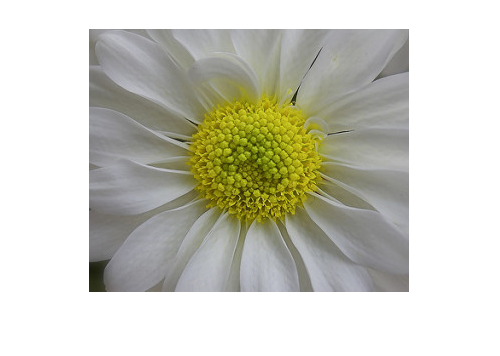

%% Load Images
% Create an |ImageDatastore| to help you manage the data. Because
% |ImageDatastore| operates on image file locations, images are not loaded
% into memory until read, making it efficient for use with large image
% collections.

imageFolder = 'C:\Users\ASUS\Documents\MATLAB\ANN Exercise 3\flower_photos\';

imds = imageDatastore(imageFolder, 'LabelSource', 'foldernames', 'IncludeSubfolders',true);
%Below, you can see an example image from one of the categories included in the dataset. The displayed image is by Mario.

% Find the first instance of an image for each category
daisy = find(imds.Labels == 'daisy', 1);

figure
imshow(readimage(imds,daisy))

%%
% The |imds| variable now contains the images and the category labels
% associated with each image. The labels are automatically assigned from
% the folder names of the image files. Use |countEachLabel| to summarize
% the number of images per category.
tbl = countEachLabel(imds)

tbl = 5×2 table
      Label       Count
    __________    _____

    daisy          633 
    dandelion      898 
    roses          641 
    sunflowers     699 
    tulips         799 


%%
% Because |imds| above contains an unequal number of images per category,
% let's first adjust it, so that the number of images in the training set
% is balanced.

minSetCount = min(tbl{:,2}); % determine the smallest amount of images in a category

% Use splitEachLabel method to trim the set.
imds = splitEachLabel(imds, minSetCount, 'randomize');

% Notice that each set now has exactly the same number of images.
countEachLabel(imds)

ans = 5×2 table
      Label       Count
    __________    _____

    daisy          633 
    dandelion      633 
    roses          633 
    sunflowers     633 
    tulips         633 


%%
% Below, you can see example images from three of the categories included
% in the dataset.

% Find the first instance of an image for each category
daisy = find(imds.Labels == 'daisy', 1);
dandelion = find(imds.Labels == 'dandelion', 1);
roses = find(imds.Labels == 'roses', 1);

figure
subplot(1,3,1);
imshow(imds.Files{daisy})
subplot(1,3,2);
imshow(imds.Files{dandelion})
subplot(1,3,3);
imshow(imds.Files{roses})

%% Download Pre-trained Convolutional Neural Network (CNN)
% Now that the images are prepared, you will need to download a pre-trained
% CNN model for this example. There are several pre-trained networks that
% have gained popularity. Most of these have been trained on the ImageNet
% dataset, which has 1000 object categories and 1.2 million training
% images[1]. "AlexNet" is one such model and can be downloaded from
% MatConvNet[2,3]:

% Location of pre-trained "AlexNet"
cnnURL = 'http://www.vlfeat.org/matconvnet/models/beta16/imagenet-caffe-alex.mat';
% Store CNN model in a temporary folder
cnnMatFile = fullfile(tempdir, 'imagenet-caffe-alex.mat');
%%
% Note: Download time of the data depends on your internet connection.  The
% next set of commands use MATLAB to download the data and will block
% MATLAB. Alternatively, you can use your web browser to first download the
% dataset to your local disk. To use the file you downloaded from the web,
% change the 'cnnMatFile' variable above to the location of the downloaded
% file.
if ~exist(cnnMatFile, 'file') % download only once     
    disp('Downloading pre-trained CNN model...');     
    websave(cnnMatFile, cnnURL);
end

%% Load Pre-trained CNN
% The CNN model is saved in MatConvNet's format [3]. Load the MatConvNet
% network data into |convnet|, a |SeriesNetwork| object from Neural Network
% Toolbox(TM), using the helper function |helperImportMatConvNet|. A
% SeriesNetwork object can be used to inspect the network architecture,
% classify new data, and extract network activations from specific layers.

% Load MatConvNet network into a SeriesNetwork
cnnMatFile = convertCharsToStrings(cnnMatFile);
convnet = helperImportMatConvNet(cnnMatFile)

convnet =   SeriesNetwork with properties:

         Layers: [23×1 nnet.cnn.layer.Layer]
     InputNames: {'input'}
    OutputNames: {'classificationLayer'}


% View the CNN architecture
convnet.Layers

ans =   23×1 Layer array with layers:

     1   'input'                 Image Input                   227×227×3 images with 'zerocenter' normalization
     2   'conv1'                 Convolution                   96 11×11×3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'                 ReLU                          ReLU
     4   'norm1'                 Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'                 Max Pooling                   3×3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'                 Grouped Convolution           2 groups of 128 5×5×48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'                 ReLU                          ReLU
     8   'norm2'                 Cross Channel Normalization   cross channel normalization with 5 channels per element
 

% Inspect the first layer
convnet.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input'
                 InputSize: [227 227 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


% Inspect the 6th layer
convnet.Layers(6)

ans =   GroupedConvolution2DLayer with properties:

                   Name: 'conv2'

   Hyperparameters
             FilterSize: [5 5]
              NumGroups: 2
    NumChannelsPerGroup: 48
     NumFiltersPerGroup: 128
                 Stride: [1 1]
         DilationFactor: [1 1]
            PaddingMode: 'manual'
            PaddingSize: [2 2 2 2]

   Learnable Parameters
                Weights: [5-D single]
                   Bias: [1×1×128×2 single]

  Show all properties


% Inspect the last layer
convnet.Layers(end)

ans =   ClassificationOutputLayer with properties:

            Name: 'classificationLayer'
         Classes: [1000×1 categorical]
      OutputSize: 1000

   Hyperparameters
    LossFunction: 'crossentropyex'


% Number of class names for ImageNet classification task
numel(convnet.Layers(end).ClassNames)

ans = 1000

%% Pre-process Images For CNN
% As mentioned above, |convnet| can only process RGB images that are
% 227-by-227. To avoid re-saving all the images in Caltech 101 to this
% format, setup the |imds| read function, |imds.ReadFcn|, to pre-process
% images on-the-fly. The |imds.ReadFcn| is called every time an image is
% read from the |ImageDatastore|.

% Set the ImageDatastore ReadFcn
imds.ReadFcn = @(filename)readAndPreprocessImage(filename);

%% Prepare Training and Test Image Sets
% Split the sets into training and validation data. Pick 30% of images
% from each set for the training data and the remainder, 70%, for the
% validation data. Randomize the split to avoid biasing the results. The
% training and test sets will be processed by the CNN model.

[trainingSet, testSet] = splitEachLabel(imds, 0.3, 'randomize');

% Get the network weights for the second convolutional layer
w1 = convnet.Layers(2).Weights;

disp(size(convnet.Layers(2).Weights));

    11    11     3    96



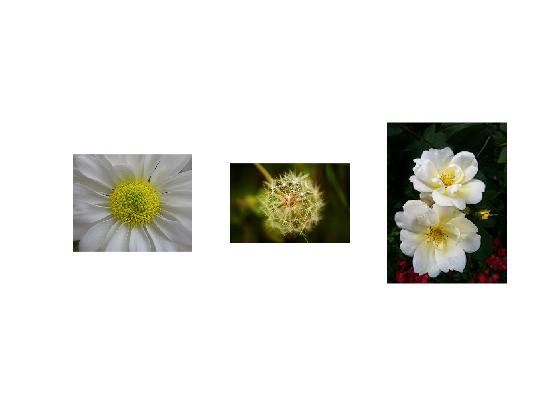


% Scale and resize the weights for visualization
w1 = mat2gray(w1);
w1 = imresize(w1,5); 
% Display a montage of network weights. There are 96 individual sets of
% weights in the first layer.
figure
montage(w1)

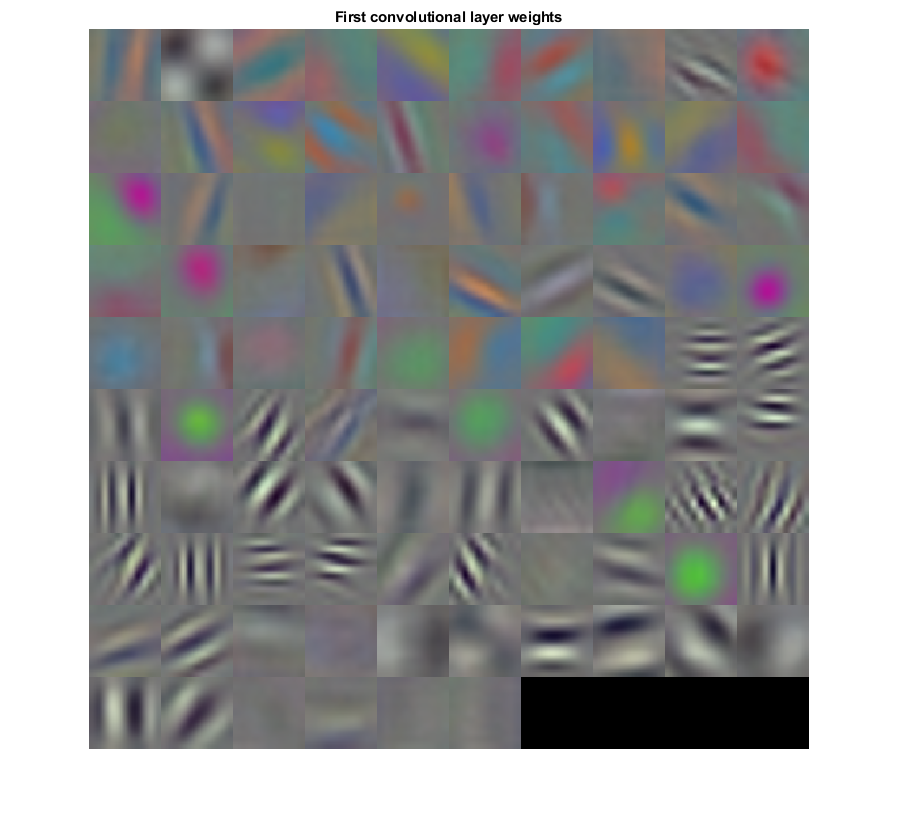

title('First convolutional layer weights')

What is the dimension of the inputs before the final classification part of the network (i.e. before the fully connected layers)? How does this compare with the initial dimension? Briefly discuss the advantage of CNNs over fully connected networks for image classification.

% Inspect the first layer
convnet.Layers(1)

ans =   ImageInputLayer with properties:

                      Name: 'input'
                 InputSize: [227 227 3]

   Hyperparameters
          DataAugmentation: 'none'
             Normalization: 'zerocenter'
    NormalizationDimension: 'auto'
                      Mean: [227×227×3 single]


% Inspect the 6th layer
convnet.Layers(6)

ans =   GroupedConvolution2DLayer with properties:

                   Name: 'conv2'

   Hyperparameters
             FilterSize: [5 5]
              NumGroups: 2
    NumChannelsPerGroup: 48
     NumFiltersPerGroup: 128
                 Stride: [1 1]
         DilationFactor: [1 1]
            PaddingMode: 'manual'
            PaddingSize: [2 2 2 2]

   Learnable Parameters
                Weights: [5-D single]
                   Bias: [1×1×128×2 single]

  Show all properties
